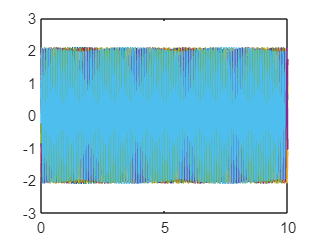

time_x = {senf020a200Ent_Time, senf060a200Ent_Time, senf500a200Ent_Time, senf550a200Ent_Time, senf600a200Ent_Time, senf650a200Ent_Time, senf700a200Ent_Time, senf750a200Ent_Time, senf800a200Ent_Time, senf850a200Ent_Time, senf900a200Ent_Time, senf950a200Ent_Time, senf1000a200Ent_Time};
time_y = {senf020a200Sai_Time(:,1), senf060a200Sai_Time(:,1), senf500a200Sai_Time(:,1), senf550a200Sai_Time(:,1), senf600a200Sai_Time(:,1), senf650a200Sai_Time(:,1), senf700a200Sai_Time(:,1), senf750a200Sai_Time(:,1), senf800a200Sai_Time(:,1), senf850a200Sai_Time(:,1), senf900a200Sai_Time(:,1), senf950a200Sai_Time(:,1), senf1000a200Sai_Time(:,1)};

x = {senf020a200Ent_Value, senf060a200Ent_Value, senf500a200Ent_Value, senf550a200Ent_Value, senf600a200Ent_Value, senf650a200Ent_Value, senf700a200Ent_Value, senf750a200Ent_Value, senf800a200Ent_Value, senf850a200Ent_Value, senf900a200Ent_Value, senf950a200Ent_Value, senf1000a200Ent_Value};
y = {senf020a200Sai_Value(:,1), senf060a200Sai_Value(:,1), senf500a200Sai_Value(:,1), senf550a200Sai_Value(:,1), senf600a200Sai_Value(:,1), senf650a200Sai_Value(:,1), senf700a200Sai_Value(:,1), senf750a200Sai_Value(:,1), senf800a200Sai_Value(:,1), senf850a200Sai_Value(:,1), senf900a200Sai_Value(:,1), senf950a200Sai_Value(:,1), senf1000a200Sai_Value(:,1)};

%for i = 1:length(time_x)
graf_init = 1;
graf_end = 13;



for i = graf_init:graf_end
    time_x{i}= time_x{i}-time_x{i}(1);
    plot(time_x{i},x{i})
    hold on
end


hold off

x_fft = cell(1,graf_end-graf_init+1);
y_fft = cell(1,graf_end-graf_init+1);

for i = graf_init:graf_end
    x_fft{i} = fft(x{i});
    y_fft{i} = fft(y{i});
end

H = cell(1,graf_end-graf_init+1)

H = 1×13 cell array
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}


for i = graf_init:graf_end
    H{i} = y_fft{i}./x_fft{i};
end

%pegando as frequências medidas
%frequencySample
frequencies = [0.2, 0.6, 2, 5, 5.5, 6, 6.5, 7, 7.5, 8, 8.5, 9, 9.5, 10];

magnitudeResponse = zeros(1,graf_end-graf_init+1)

magnitudeResponse =      0     0     0     0     0     0     0     0     0     0     0     0     0


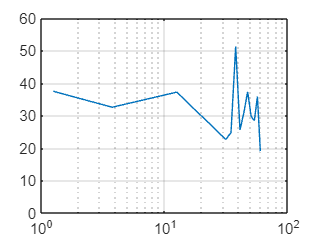

phaseResponse = cell(1,graf_end-graf_init+1);

for i = graf_init:graf_end
    [magnitudeResponse(i),  index]= max(abs(H{i}));
    phaseResponse{i} = rad2deg(angle(H{i}(index)));
end
figure;

omega = zeros(graf_end-graf_init+1);
ampl = zeros(graf_end-graf_init+1);

for i = graf_init:graf_end
    omega(i) = 2*pi*frequencies(i);
    ampl(i) = 20*log10(magnitudeResponse(i));
end

semilogx(omega,ampl,'-')
grid on

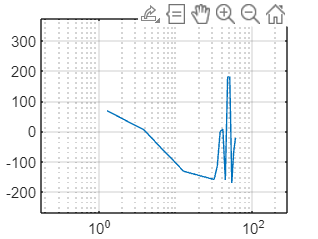


fase = zeros(graf_end-graf_init+1);

for i = graf_init:graf_end
    fase(i) = phaseResponse{i};
end

semilogx(omega, fase)
grid on